# LCE-04 MOSFET

## cs frequency response

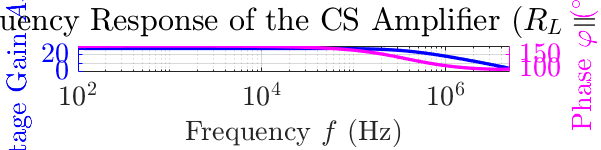

data_cs_freq = readmatrix("D:\aa_MyExperimentData\LCE (Linear Circuit Experiment)\LCE-04 场效应 2025-04-25\cs amp frequency response (input 100 mVamp, 100Hz ~ 5MHz).txt");
% Frequency (Hz)	Trace < (deg)	Trace th (deg)	Trace Vin (V)	Trace Vout (V)	Trace Vout/Vin (V)
f = data_cs_freq(:, 1);
phase_1 = - data_cs_freq(:, 2);
A_v = data_cs_freq(:, 6);
A_v_dB = 20*log(A_v)/log(10);

%theta = data_cs_freq(:, 2);
stc = MyYYPlot(f', f', A_v_dB', phase_1');
stc.axes.XScale = 'log';
yyaxis('left')
stc.axes.YLim = [0 30];
yyaxis('right')
stc.axes.YLim = [90 180];
stc.leg.Visible = 'off';
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y_left.String = 'Voltage Gain $A_v$ (dB)';
stc.label.y_right.String = 'Phase $\varphi\ (^\circ)$';
stc.axes.Title.String = 'Frequency Response of the CS Amplifier ($R_L = \infty$)';
MyFigure_ChangeSize_2048x512

%MyExport_pdf

## cs output impedance

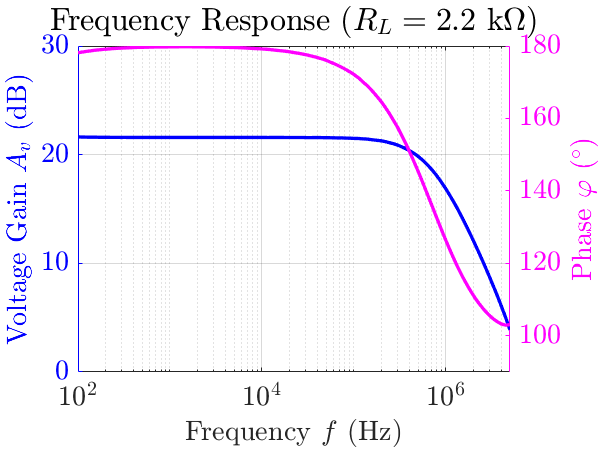

data_cs_outImpe = readmatrix("D:\aa_MyExperimentData\LCE (Linear Circuit Experiment)\LCE-04 场效应 2025-04-25\cs amp output impedance, R_L = 2k2 Ohm (input 100 mVamp, 100Hz ~ 5MHz).txt");
f = data_cs_outImpe(:, 1);
phase_2 = - data_cs_outImpe(:, 2);
A_v_2 = data_cs_outImpe(:, 6);
A_v_2_dB = 20*log(A_v_2)/log(10);

stc = MyYYPlot(f', f', A_v_2_dB', phase_2');
stc.axes.XScale = 'log';
yyaxis('left')
stc.axes.YLim = [0 30];
yyaxis('right')
stc.axes.YLim = [90 180];
stc.leg.Visible = 'off';
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y_left.String = 'Voltage Gain $A_v$ (dB)';
stc.label.y_right.String = 'Phase $\varphi\ (^\circ)$';
stc.axes.Title.String = 'Frequency Response ($R_L = 2.2\ \mathrm{k}\Omega$)';

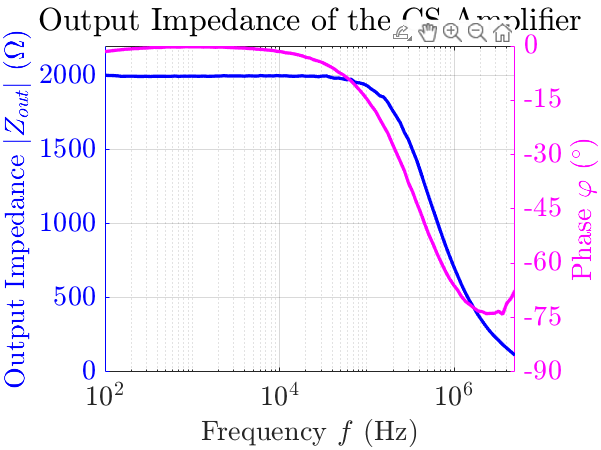

%MyFigure_ChangeSize_2048x512

R_L = 2200;

if 0
% 忽略相位, 忽略输出电容分压, 近似计算:
Z_C = 1/(2*pi*100*22e-6);
Z_out_abs_approx = (A_v./A_v_2 - 1)*R_L;
stc = MyPlot(f, Z_out_abs_approx);
stc.axes.XScale = 'log';
end

% 不忽略相位, 精确计算:
% 将增益转化为复数量
A_1 = A_v.*cosd(phase_1) + 1j*A_v.*sind(phase_1);
A_2 = A_v_2.*cosd(phase_2) + 1j*A_v_2.*sind(phase_2);
C_out = 22e-6;
Z_out = (A_1./A_2 - 1) .* (R_L + 1./(1j*2*pi*f*C_out));
angle_Z_out = MyArcTheta_deg(real(Z_out), imag(Z_out)) - 360;

stc = MyYYPlot(f, f, abs(Z_out), angle_Z_out);
stc.axes.XScale = 'log';
yyaxis('left')
stc.axes.YLim = [0 2200];
yyaxis('right')
stc.axes.YLim = [-90 0];
stc.axes.YTick = -90:15:0;
%stc.axes.YTickLabel = -90:15:0;
stc.leg.Visible = 'off';
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y_left.String = 'Output Impedance $|Z_{out}|\ (\Omega)$';
stc.label.y_right.String = 'Phase $\varphi\ (^\circ)$';
stc.axes.Title.String = 'Output Impedance of the CS Amplifier';

## cs input impedance

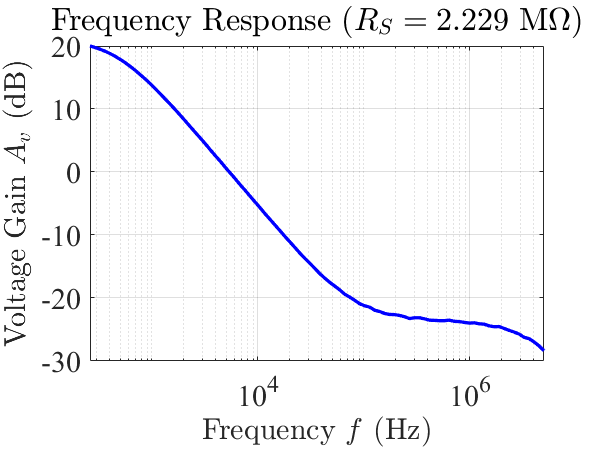

data_cs_inpImpe = readmatrix("D:\aa_MyExperimentData\LCE (Linear Circuit Experiment)\LCE-04 场效应 2025-04-25\cs amp input impedance, R_S = 2M229 (input 100 mVamp, 100Hz ~ 5MHz).txt");
f = data_cs_inpImpe(:, 1);
V_out = data_cs_inpImpe(:, 2);
A_v_2 = V_out/0.1;
A_v_2_dB = 20*log(A_v_2)/log(10);

stc = MyPlot(f, A_v_2_dB);
stc.axes.XScale = 'log';
stc.axes.YLim = [-30 20];
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y.String = 'Voltage Gain $A_v$ (dB)';
stc.axes.Title.String = 'Frequency Response ($R_S = 2.229\ \mathrm{M}\Omega$)';
stc.plot.plot_1.Color = 'b';

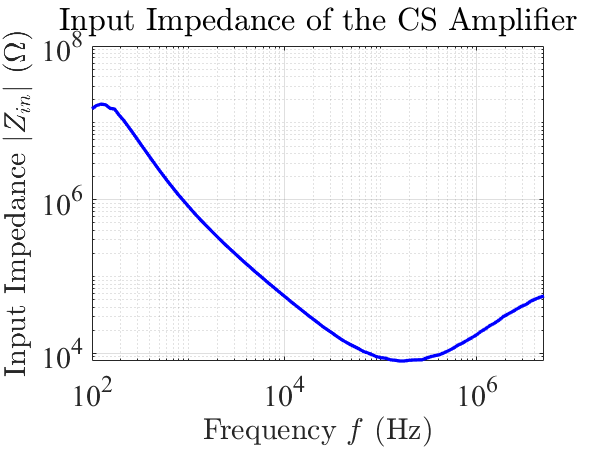


R_S = 2.229e6;
R_G = 2.230e6;

if 1
% 忽略相位, 忽略输入电容分压, 近似计算:
Z_in_paral_abs_approx = R_S./(A_v./A_v_2 - 1);
Z_in_abs_approx = 1./(1./Z_in_paral_abs_approx - 1/R_G);
stc = MyPlot(f, Z_in_abs_approx);
stc.axes.XScale = 'log';
stc.axes.YScale = 'log';
stc.axes.YLim = [0 1e8];
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y.String = 'Input Impedance $|Z_{in}|\ (\Omega)$';
stc.axes.Title.String = 'Input Impedance of the CS Amplifier';
stc.plot.plot_1.Color = 'b';
end


% 没有第二条曲线的相位数据, 不能精确计算

## cd frequency response

clc, clear, close all
disp('------------------------------------------------------------')

------------------------------------------------------------


disp('------------------------------------------------------------')

------------------------------------------------------------


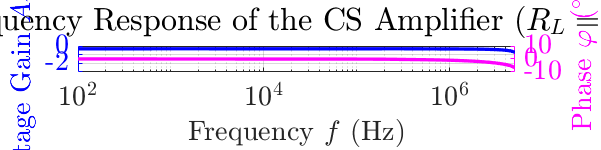

data_cd_freq = readmatrix("D:\aa_MyExperimentData\LCE (Linear Circuit Experiment)\LCE-04 场效应 2025-04-25\cd amp frequency response (input 2 Vamp, 100Hz ~ 5MHz).txt");
% Frequency (Hz)	Trace < (deg)	Trace th (deg)	Trace Vin (V)	Trace Vout (V)	Trace Vout/Vin (V)
f = data_cd_freq(:, 1);
A_v = data_cd_freq(:, 6);
A_v_dB = 20*log(A_v)/log(10);
phase_1 = - data_cd_freq(:, 2);

%theta = data_cd_freq(:, 2);
stc = MyYYPlot(f', f', A_v_dB', phase_1');
stc.axes.XScale = 'log';
yyaxis('left')
stc.axes.YLim = [-3 0];
yyaxis('right')
stc.axes.YLim = [-10 10];
stc.leg.Visible = 'off';
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y_left.String = 'Voltage Gain $A_v$ (dB)';
stc.label.y_right.String = 'Phase $\varphi\ (^\circ)$';
stc.axes.Title.String = 'Frequency Response of the CS Amplifier ($R_L = \infty$)';
MyFigure_ChangeSize_2048x512

## cd output impedance

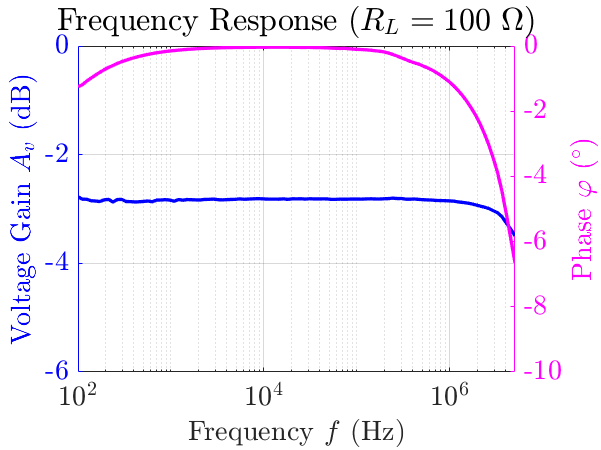

data_cs_outImpe = readmatrix("D:\aa_MyExperimentData\LCE (Linear Circuit Experiment)\LCE-04 场效应 2025-04-25\cd amp output impedance, R_L = 100 Ohm (input 2 Vamp, 100Hz ~ 5MHz).txt");
f = data_cs_outImpe(:, 1);
phase_2 = - data_cs_outImpe(:, 2);
A_v_2 = data_cs_outImpe(:, 6);
A_v_2_dB = 20*log(A_v_2)/log(10);

stc = MyYYPlot(f', f', A_v_2_dB', phase_2');
stc.axes.XScale = 'log';
yyaxis('left')
stc.axes.YLim = [-6 0];
yyaxis('right')
stc.axes.YLim = [-10 0];
stc.leg.Visible = 'off';
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y_left.String = 'Voltage Gain $A_v$ (dB)';
stc.label.y_right.String = 'Phase $\varphi\ (^\circ)$';
stc.axes.Title.String = 'Frequency Response ($R_L = 100\ \Omega$)';

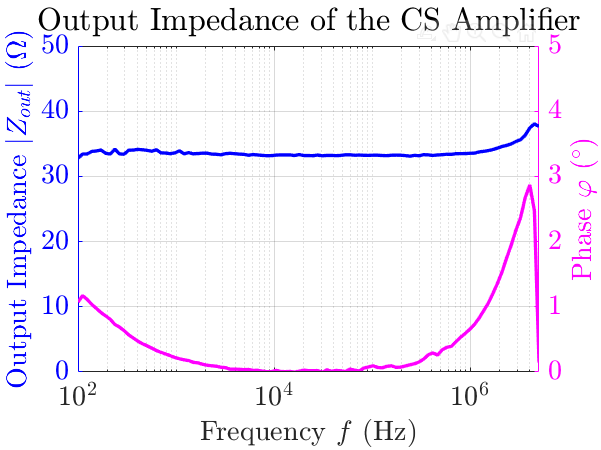


R_L = 100;

% 不忽略相位, 精确计算:
% 将增益转化为复数量
A_1 = A_v.*cosd(phase_1) + 1j*A_v.*sind(phase_1);
A_2 = A_v_2.*cosd(phase_2) + 1j*A_v_2.*sind(phase_2);
C_out = 220e-6;
Z_out = (A_1./A_2 - 1) .* (R_L + 1./(1j*2*pi*f*C_out));
angle_Z_out = MyArcTheta_deg(real(Z_out), imag(Z_out));

angle_Z_out(angle_Z_out > 300) = angle_Z_out(angle_Z_out > 300) - 360;
stc = MyYYPlot(f, f, abs(Z_out), angle_Z_out);
stc.axes.XScale = 'log';
yyaxis('left')
stc.axes.YLim = [0 50];
yyaxis('right')
stc.axes.YLim = [0 5];
stc.leg.Visible = 'off';
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y_left.String = 'Output Impedance $|Z_{out}|\ (\Omega)$';
stc.label.y_right.String = 'Phase $\varphi\ (^\circ)$';
stc.axes.Title.String = 'Output Impedance of the CS Amplifier';

## cd input impedance

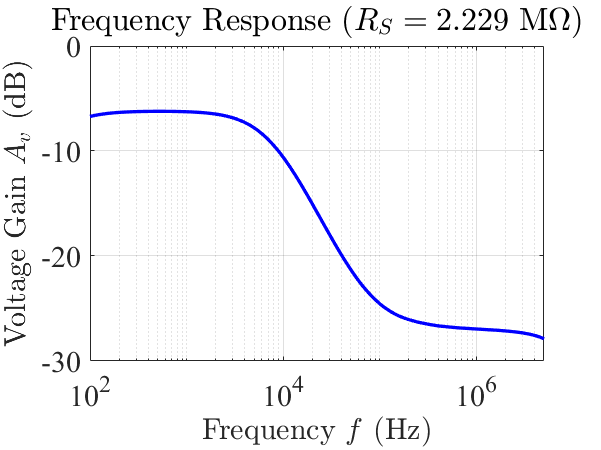

% 没有第二条曲线的相位数据, 不能精确计算

data_cd_inpImpe = readmatrix("D:\aa_MyExperimentData\LCE (Linear Circuit Experiment)\LCE-04 场效应 2025-04-25\cd amp input impedance, R_S = 2M229 (input 2 Vamp, 100Hz ~ 5MHz).txt");
f = data_cd_inpImpe(:, 1);
V_out = data_cd_inpImpe(:, 2);
A_v_2 = V_out/2;
A_v_2_dB = 20*log(A_v_2)/log(10);

stc = MyPlot(f, A_v_2_dB);
stc.axes.XScale = 'log';
stc.axes.YLim = [-30 0];
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y.String = 'Voltage Gain $A_v$ (dB)';
stc.axes.Title.String = 'Frequency Response ($R_S = 2.229\ \mathrm{M}\Omega$)';
stc.plot.plot_1.Color = 'b';

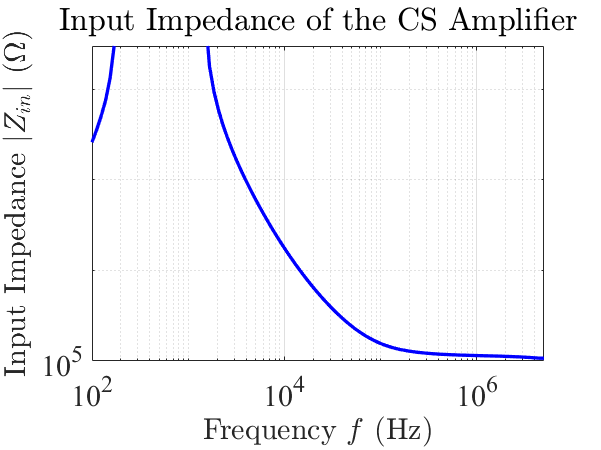



R_S = 2.229e6;

if 1
% 忽略相位, 忽略输入电容分压, 近似计算:
Z_in_paral_abs_approx = R_S./(A_v./A_v_2 - 1);
Z_in_abs_approx = 1./(1./Z_in_paral_abs_approx - 1/R_S);
stc = MyPlot(f, Z_in_abs_approx);
stc.axes.XScale = 'log';
stc.axes.YScale = 'log';
stc.axes.YLim = [10^5 3e8];
stc.label.x.String = 'Frequency $f$ (Hz)';
stc.label.y.String = 'Input Impedance $|Z_{in}|\ (\Omega)$';
stc.axes.Title.String = 'Input Impedance of the CS Amplifier';
stc.plot.plot_1.Color = 'b';
end